system parameters:

m1 = 1;     % mass of the cart
m2 = 0.1;   % mass of the pendulum
l = 0.5;    % length of the pendulum
g = 9.81;   % acceleration due to gravity

state space matrices:

A = [0 0 1 0; 0 0 0 1; 0 m2*g/m1 0 0; 0 (m1+m2)*g/(l*m1) 0 0];
B = [0; 0; 1/m1; 1/(l*m1)];
C = eye(4);
D = zeros(4,1);

state space model:

sys = ss(A,B,C,D);

initial conditions:

x0 = [0; pi/6; 0; 0];

input function:

tspan = 0:0.01:10;         % time span for simulation
F = @(t) 0.1*sin(2*pi*t);  % input function

Simulate the system using the input function:

[t,x] = ode45(@(t,x) inputFcn(t,x,F,sys), tspan, x0);

plotting:

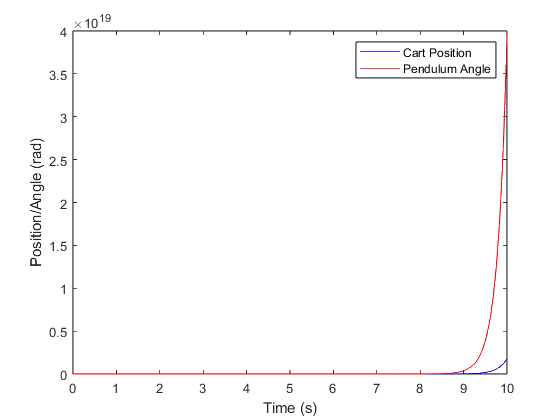

plot(t,x(:,1),'b',t,x(:,2),'r');
legend('Cart Position','Pendulum Angle');
xlabel('Time (s)');
ylabel('Position/Angle (rad)');

**SMC Controller:**

Define the design parameters:

lambda = 1;
k1 = 10;
k2 = 5;

Define the sliding surface and control law:

Simulate the closed-loop system with the SMC controller:

lambda = 1;
k1 = 10;
k2 = 5;

tspan = 0:0.01:10;         % time span for simulation
F = @(t) 0.1*sin(2*pi*t);  % input function

% Simulation using the SMC controller
[t,x] = ode45(@(t,x) smcFcn(t,x,F,m1,m2,l,g,lambda,k1,k2), tspan, x0);



plotting:

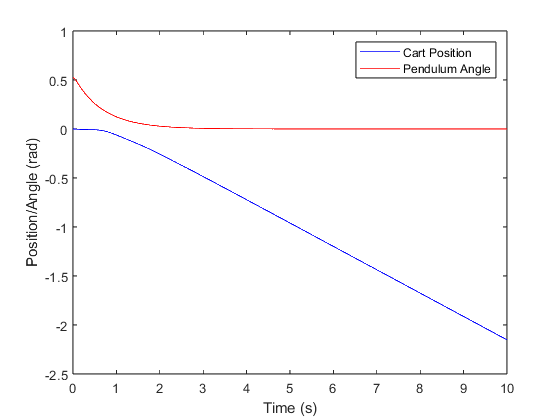

figure(2)
plot(t,x(:,1),'b',t,x(:,2),'r');
legend('Cart Position','Pendulum Angle');
xlabel('Time (s)');
ylabel('Position/Angle (rad)');

`inputFcn` function is defined as:

function xdot = inputFcn(t,x,F,sys)
    u = F(t);
    xdot = sys.A * x + sys.B * u;
end

`smcFcn` function is defined as:

function xdot = smcFcn(t,x,F,m1,m2,l,g,lambda,k1,k2)
    theta = x(2);
    theta_dot = x(4);
    s = theta + lambda*theta_dot;
    u = -sign(s)*(k1*abs(s) + k2*abs(theta_dot));
    F_val = F(t);
    xdot = zeros(4,1);
    xdot(1) = x(3);
    xdot(2) = x(4);
    xdot(3) = (m2*l*sin(theta)*theta_dot^2 + F_val*u - m2*g*cos(theta)*sin(theta)) / (m1 + m2*sin(theta)^2);
    xdot(4) = (-m2*l*cos(theta)*sin(theta)*theta_dot^2 + u*cos(theta) - (m1+m2)*g*sin(theta)) / (l*(m1+m2*sin(theta)^2));
end
